# Aula 10 - Laboratório de Controle - 2021/1

# Projeto do controlador via realimentação de estados+observador

## Nome: Lucas Neves Gobbo

turma=5 ;
I=5 ;
Tempo=3;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);

arquivo='aula10_R2019.slx'; 

load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));

L=[0;0];
K=[0 0];
RI=0;
Ki=0;
p1=0;
y0=0;


## Atividade 1 - Obtenção do modelo em variáveis de estados e simulação em malha aberta

Modelo em variáveis de estado e função de transferência


$$\dot{x}=Ax+Bu \\
y=Cx\\
\frac{Y(s)}{U(s)}=C(sI-A)^{-1}B$$


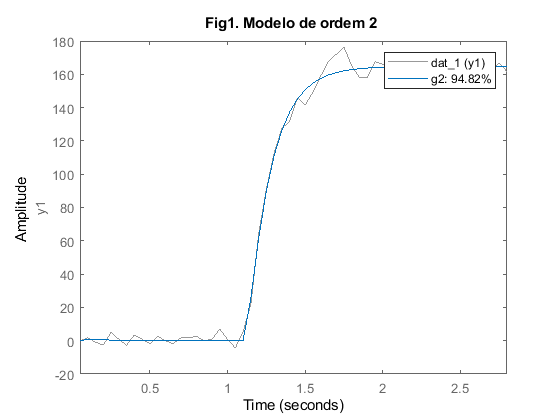

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
Kp=freqresp(g2,0);
figure
compare(dat_1,g2);title('Fig1. Modelo de ordem 2 ');

[A,B,C,D]=tf2ss(g2.num{1},g2.den{1});
sys=ss(A,B,C,D);

Kp=freqresp(g2,0); 
Ts=0.01; 
s=stepinfo(g2);
ts_ma=s.SettlingTime;
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));
[Y,t]=simula_slx(arquivo,1);
i1=sum(t<2);
y0=mean(Y((i1-10):i1,3));
Tabela1=table(Ref,ts_ma,u0,y0)

Tabela1 = 1×4 table
    Ref     ts_ma     u0       y0  
    ____    ______    ___    ______

    2767    0.6157    122    2511.1


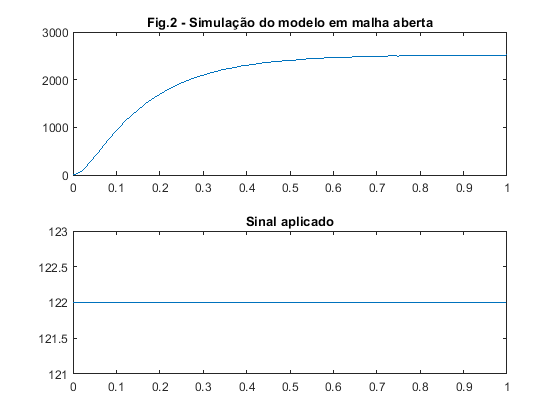

figure
subplot(2,1,1);plot(t,Y(:,[3]));title('Fig.2 - Simulação do modelo em malha aberta');
subplot(2,1,2);plot(t,Y(:,2));title('Sinal aplicado');

1.1 Quantas entradas, quantas saídas, e quantos estados tem o modelo em variáveis de estados armazenado na variável sys? 

Explicar.

Temos uma variável de entrada, uma de saída e dois estados. Ao analisar 'A', vemos que o vetor de espaço x tem dimensão 2, logo dois estados. O vetor de saída y tem apenas uma dimensão, logo uma saída apenas. O vetor de entrada u tem apenas uma dimensão também, logo uma entrada.

## Atividade 2 - Projetar a realimentação de estados e o observador

A figura abaixo mostra a estratégia de controle utilizada. A realimentação de estados da forma $u=Ref-K\tilde{x}$ precisa dos estados, mas apenas a saída $y$ é medida. Para isto se constrói um observador, que envolve calcular o vetor de ganhos $L$ tal que os autovalores de $(A-L*C)$ tenham todos parte real negativa. Com isto, se substitui os estados $x$ por sua estimativa $\tilde{x}$ no controle. O vetor de ganhos da realimentação de estados $K$é calculado tal que os autovalores de $(A-B*K)$sejam os polos do modelo de referência, que tem uma sobreelevação Up e um tempo de estabelecimento iguais aos desejados.

Usar o modelo de referência gesp definido por UPe e tse para definir os polos de malha fechada do controlador por realimentação de estados. Usar valores obtidos dos projetos anteriores.

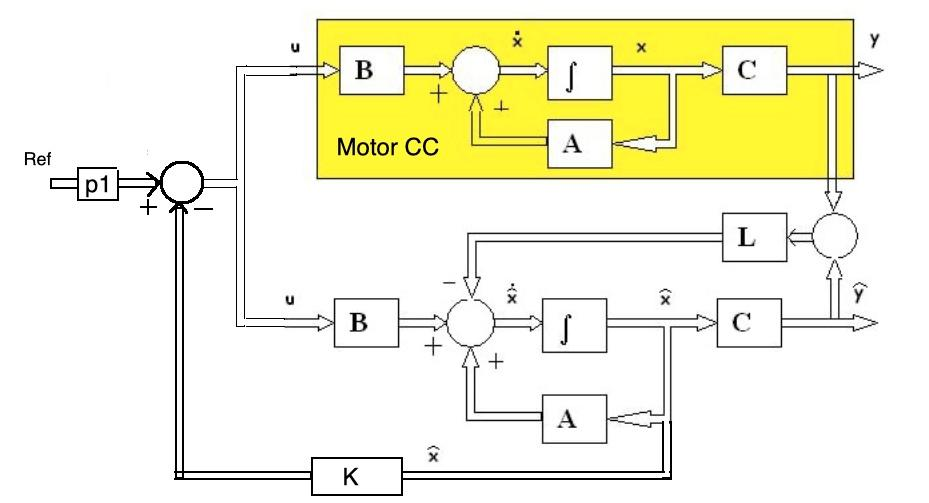

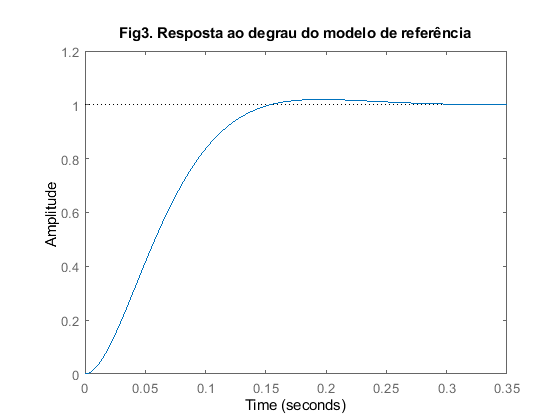

UPe=2 ; 
tse=0.2 ;
a=log(UPe/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(tse*zeta);
gesp=tf(wn^2,[1 2*zeta*wn wn^2]);
figure;
step(gesp);title('Fig3. Resposta ao degrau do modelo de referência');

Escolhendo agora os polos de malha fechada da realimentação de estados

polos_malhafechada=pole(gesp);

Escolhendo agora os polos do observador de estados, que devem ser n vezes mais rápidos que os polos do controlador da realimentação de estados

n=6;
polos_observador=n*polos_malhafechada;

Calculando as matrizes de ganho da realimentação de estados K e do observador de estados L

K=place(A,B,polos_malhafechada);Kt=K';  
L=place(A',C',polos_observador);L=L';

Tabela com o resumo do projeto:

Tabela_polos_e_ganhos=table(polos_malhafechada,polos_observador,Kt,L)

Tabela_polos_e_ganhos = 2×4 table
    polos_malhafechada    polos_observador       Kt          L    
    __________________    ________________    ________    ________

       -20+16.061i          -120+96.367i      -0.54986      4.9307
       -20-16.061i          -120-96.367i        430.82    0.063977


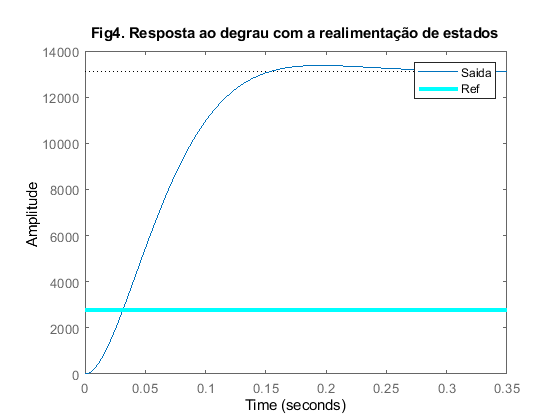

m=ss(A-B*K,B,C,D); 
figure
step(Ref*m);title('Fig4. Resposta ao degrau com a realimentação de estados');
line([0 0.5],[Ref Ref], 'Color','c','LineWidth',3); legend('Saida','Ref');

2.1 Compare e resposta do modelo de referência e a obtida pela realimentação de estados (UP, ts, erro em regime). Dica: a referência a seguir está na Tabela 1.

K_gesp=freqresp(gesp,0);
K_m=freqresp(m,0);
tabela_ganhos=table(K_gesp,K_m)

tabela_ganhos = 1×2 table
    K_gesp     K_m  
    ______    ______

      1       4.7382


2.2 Compare os ganhos do modelo de referência e do sistema de MF resultante e calcule p1 para que p1*M(s) tenha o mesmo ganho que gesp. Explique o cálculo.

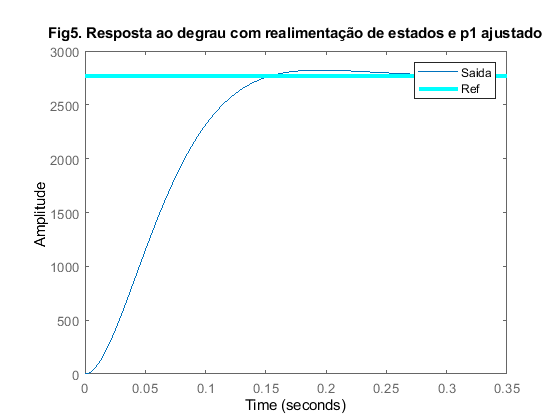

p1=1/K_m;  
figure
step(Ref*p1*m);title('Fig5. Resposta ao degrau com realimentação de estados e p1 ajustado');
line([0 0.5],[Ref Ref], 'Color','c','LineWidth',3); legend('Saida','Ref');

Simule o controlador no modelo do motor (slx). 

p1=1/50;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UPp,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);
Tipo={'Especificacoes';'Obtido';};
UP=[UPe;UPp];ts=[tse;SettlingTime];Erro=[0;erro];
Tabela1=table(Tipo,UP,ts,Erro)

Tabela1 = 2×4 table
           Tipo             UP        ts        Erro  
    __________________    ______    _______    _______

    {'Especificacoes'}         2        0.2          0
    {'Obtido'        }    1.4961    0.14437    0.26185


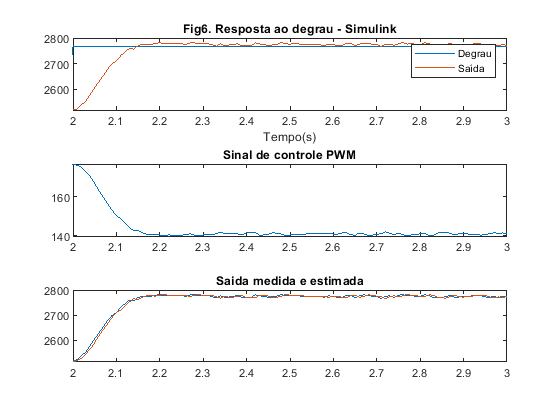


figure
subplot(3,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig6. Resposta ao degrau - Simulink');xlim([2 Tempo]);
subplot(3,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo]);
subplot(3,1,3);plot(t,Y(:,[3,4]));title('Saida medida e estimada');xlim([2 Tempo]);

2.3 Compare a resposta das figuras 5 e 6, justifique as diferenças, e discuta formas de fazer com que a simulação obtida no motor (fig 6) se aproxime da desejada (modelo de referência), ajustando p1, por exemplo.

As figuras 5 e 6 mostram o efeito da resposta ao degrau com realimentação dos estados. Na Figura 5, temos usando o p1 = 1/K_m para poder ajustar o valor de saída para ficar o mais próximo possível da referência. Na Figura 6, o p1 é estimado para o nosso caso real, para que tenhamos um bom sinal de controle no PWM e uma saída estimada bem próxima da saída medida. Para a figura 6 ficar o mais próxima possível da figura 5, devemos ajustar p1 para controlar o ganho e ajustar o 'n' para aumentar a velocidade de resposta, mas não aumentar tanto a ponto de só ter ruído.

O ganho K da realimentação de estados e o ganho L do observador de estados podem ser transformados em compensadores C1 e C2 (figura abaixo) aplicados à FT do motor. Basta para isto aplicar a transformada de Laplace  ao sistema em variáveis de estado. isto é feito nas linhas de código abaixo.

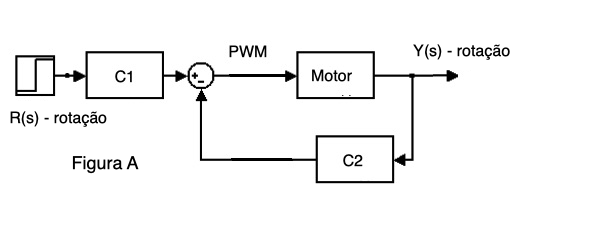

[NC1,DC1]=ss2tf(A-L*C-B*K,B,K,0,1); 
[NC2,DC2]=ss2tf(A-L*C-B*K,L,K,0,1);
C1=1-tf(NC1,DC1)

C1 =
 
   s^2 + 240 s + 2.369e04
  ------------------------
  s^2 + 239.5 s + 2.401e04
 
Continuous-time transfer function.



C2=tf(NC2,DC2)

C2 =
 
       24.85 s + 3250
  ------------------------
  s^2 + 239.5 s + 2.401e04
 
Continuous-time transfer function.



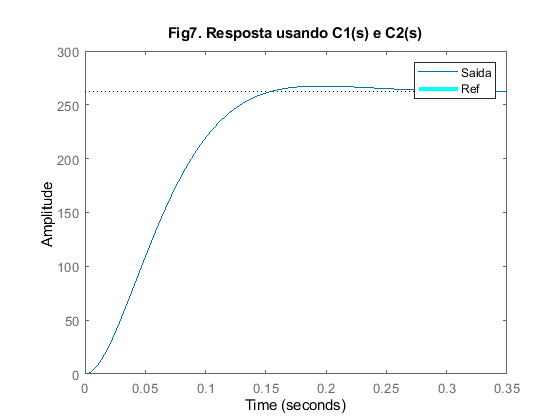

M_re=C1*feedback(g2,C2);
M_re_minima=minreal(M_re);
figure
step(Ref*M_re_minima*p1);
line([0 1],[Ref Ref], 'Color','c','LineWidth',3);
title('Fig7. Resposta usando C1(s) e C2(s)');legend('Saida','Ref');

2.4 Qual a ordem de $Y(s)/R(s)$ na Figura B? Qual a ordem da FT M_re_minima? Explique a diferença. Dica: analise os polos e zeros das FTs.

É de terceira ordem na figura B. A ordem da FT M_re_minima é de segunda ordem. No primeiro, é adicionado um polo para poder ficar mais fácil de zerar o erro.

Varie os polos do observador tornado-os cada vez mais rápidos que os da  realimentação de malha fechada, e refaça a simulação.

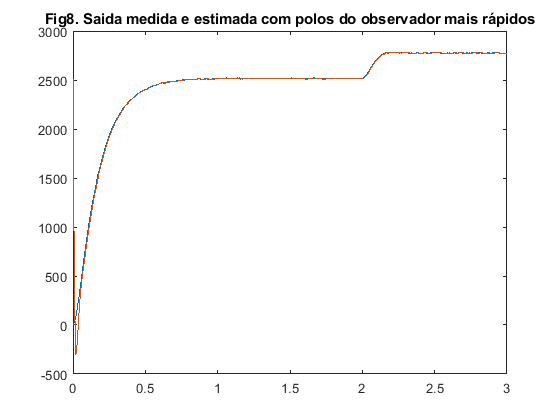

n=5;
polos_observador=n*polos_malhafechada; 
L=place(A',C',polos_observador);L=L';

[Y,t]=simula_slx(arquivo,Tempo);
figure;
plot(t,Y(:,[3,4]));title('Fig8. Saida medida e estimada com polos do observador mais rápidos');

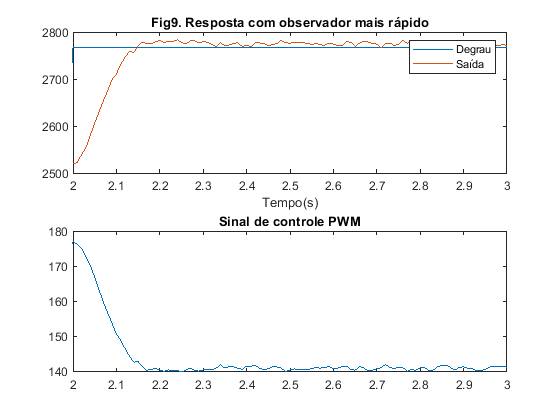

figure
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');xlim([2 Tempo])
title('Fig9. Resposta com observador mais rápido');
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo])

2.5 Compare o tempo para o erro da estimativa do estado tender a zero, bem como o comportamento do sinal de controle e da saída, quando varia a localização dos polos do observador.

## Atividade 3 - Realimentação integral de estados

A figura B mostra a configuração da realimentação integral de estados, com o vetor de ganhos K que realimenta os estados originais e o ganho adicional Ki que realimenta o novo estado introduzido pelo integrador. Para esta simulação, faz-se p1=1 e RI=1 (habilita o integrador). 

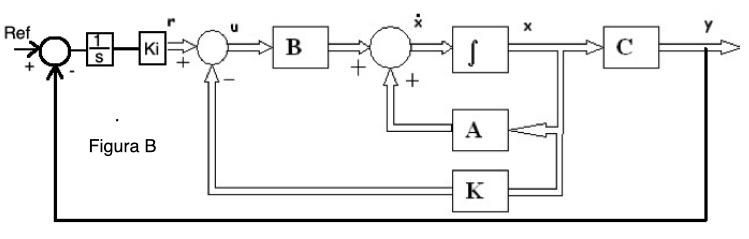

p1=1; 
RI=1; 

Sistema aumentado (adição do integrador)

Aa=[A [0;0]; -C 0]; 
Ba=[B;0];
B2=[0;0;1];
Ca=[C 0];

O terceiro polo p3 deve ser adequadamente escolhido. Teste valores menores e maiores que a parte real dos polos do modelo de referência.

p3=-10; 
polos_malhafechada_i=[polos_malhafechada; p3];  
K=place(Aa,Ba,polos_malhafechada_i);
Ki=K(3);
K=[K(1) K(2)];

[Y,t]=simula_slx(arquivo,Tempo);

[erro_i,UP_i,SettlingTime_i] = desempenho(Y(:,[2,3]),t,Ref,2);
Tipo_de_controle={'Especificacoes';'Realimentação estados';'Integral'};
UP=[UPe;UPp;UP_i];ts=[tse;SettlingTime;SettlingTime_i];Erro=[0;erro;erro_i];
Tabela2=table(Tipo_de_controle,UP,ts,Erro)

Tabela2 = 3×4 table
        Tipo_de_controle           UP         ts         Erro  
    _________________________    _______    _______    ________

    {'Especificacoes'       }          2        0.2           0
    {'Realimentação estados'}     1.4961    0.14437     0.26185
    {'Integral'             }    0.16246    0.35875    0.020493


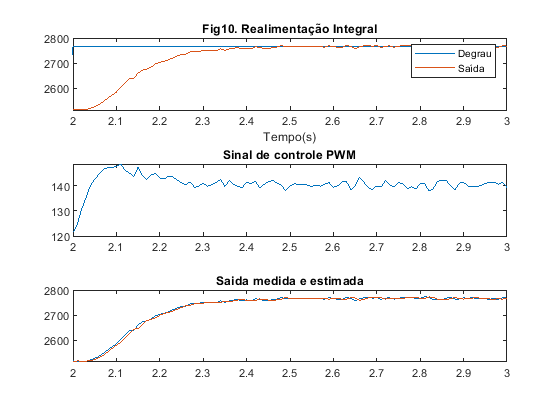


figure;
subplot(3,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');
xlabel('Tempo(s)');title('Fig10. Realimentação Integral');xlim([2 Tempo])
subplot(3,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');xlim([2 Tempo])
subplot(3,1,3);plot(t,Y(:,[3,4]));title('Saida medida e estimada');xlim([2 Tempo])

3.1 Qual o efeito da localização do polo real da realimentacão integral p3 sobre a resposta transitória e sobre o sinal de controle? 

O efeito da localização de p3, se ele for muito à esquerda, pode causar instabilidades e oscilações na resposta transitória e no sinal de controle. Com p3 mais à direita, temos que tanta a resposta transitória fica melhor quanto o sinal de controle menos oscilatório.

3.2 Compare as Tabelas 2 e 3.

Vemos que o modo integral faz o erro ficar bem próximo de zero, mais próximo do que qualquer outro método, pois ele faz a integral do erro.

3.3 Compare o projeto do PID com o da realimentacao integral de estados, destacando vantagens/desvantagens dos métodos

PID (Vantagens): 

datetime('now')

ans = datetime
   28-Aug-2021 17:23:03


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Aula10'